参数灵敏度分析

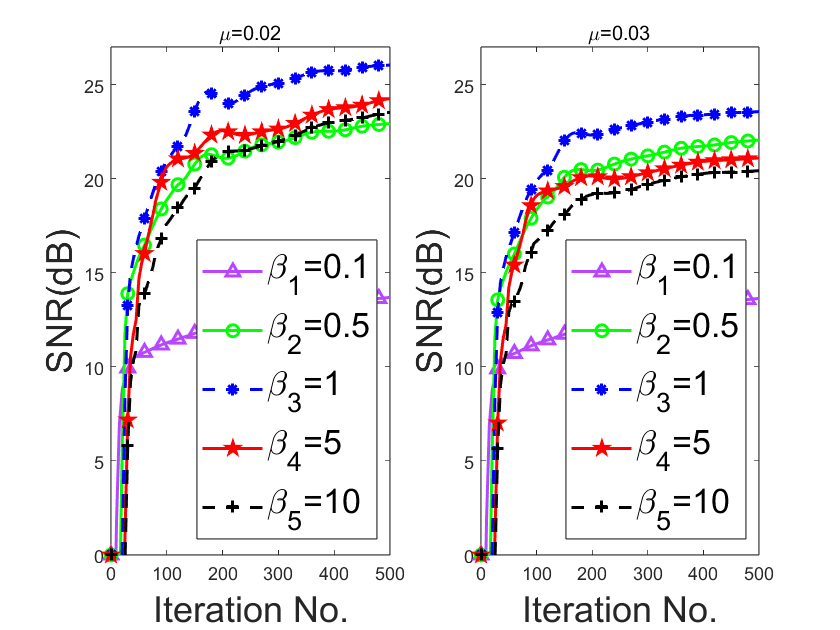

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = [0.1,0.5,1,5,10];

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 500;
opts1.snr = 50;
[~,N] = size(beita);
reimed1 = zeros(N,rows,cols);reimed2 = zeros(N,rows,cols);
for i = 1:N
    [reimed1(i,:,:),outs1(i)] = hypd_tv_me2_adaptive(fn1,W,beita(i),rows,cols,im,opts1);
    [reimed2(i,:,:),outs2(i)] = hypd_tv_me2_adaptive(fn2,W,beita(i),rows,cols,im,opts1);
end

%% 绘图
Xaxis = (0:5:500);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\beta_1=0.1}','{\beta_2=0.5}','{\beta_3=1}','{\beta_4=5}','{\beta_5=10}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.02','FontSize',19);

subplot(122);
plot(Xaxis,outs2(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\beta_1=0.1}','{\beta_2=0.5}','{\beta_3=1}','{\beta_4=5}','{\beta_5=10}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.03','FontSize',19);

% set(gcf,'unit','centimeters','position',[1,2,30,12])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg2_1.beita.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg2_1.beita.fig')

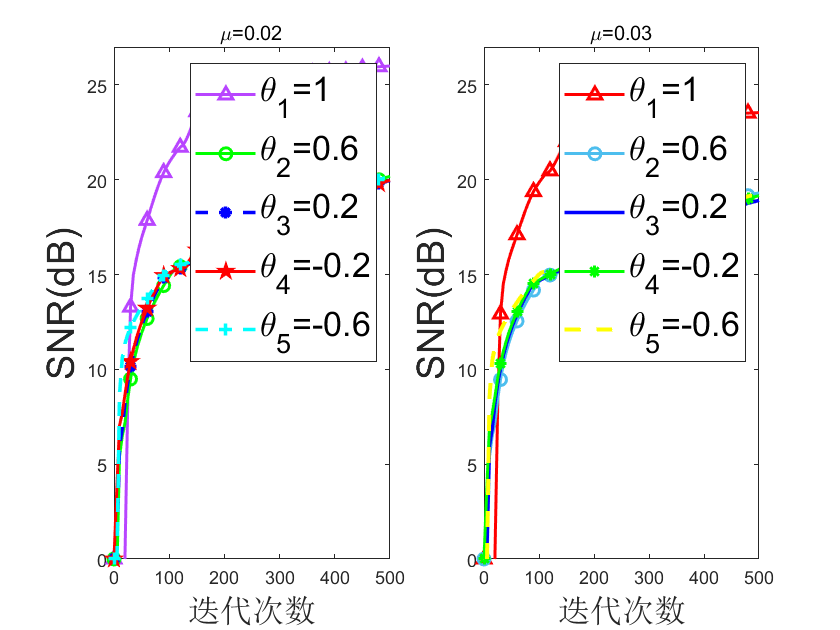

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 500;
opts1.snr = 50;
theta = [1,0.6,0.2,-0.2,-0.6];
[~,N] = size(theta);
reimed1 = zeros(N,rows,cols);reimed2 = zeros(N,rows,cols);
for i = 1:N
    if theta(i) == 1
        [reimed1(i,:,:),outs1_1] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);
        [reimed2(i,:,:),outs2_1] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);
    else 
        opts1.theta = theta(i);
        [reimed1(i,:,:),outs1(i)] = hypd_tv_me1_adaptive(fn1,W,beita,rows,cols,im,opts1);
        [reimed2(i,:,:),outs2(i)] = hypd_tv_me1_adaptive(fn2,W,beita,rows,cols,im,opts1);
    end
end

%% 绘图
Xaxis = (0:5:500);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1_1.snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\theta_1=1}','{\theta_2=0.6}','{\theta_3=0.2}','{\theta_4=-0.2}','{\theta_5=-0.6}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.02','FontSize',19);

subplot(122);
plot(Xaxis,outs2_1.snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\theta_1=1}','{\theta_2=0.6}','{\theta_3=0.2}','{\theta_4=-0.2}','{\theta_5=-0.6}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.03','FontSize',19);

% set(gcf,'unit','centimeters','position',[1,2,30,12])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg2_2.theta.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg2_2.theta.fig')

## gamma

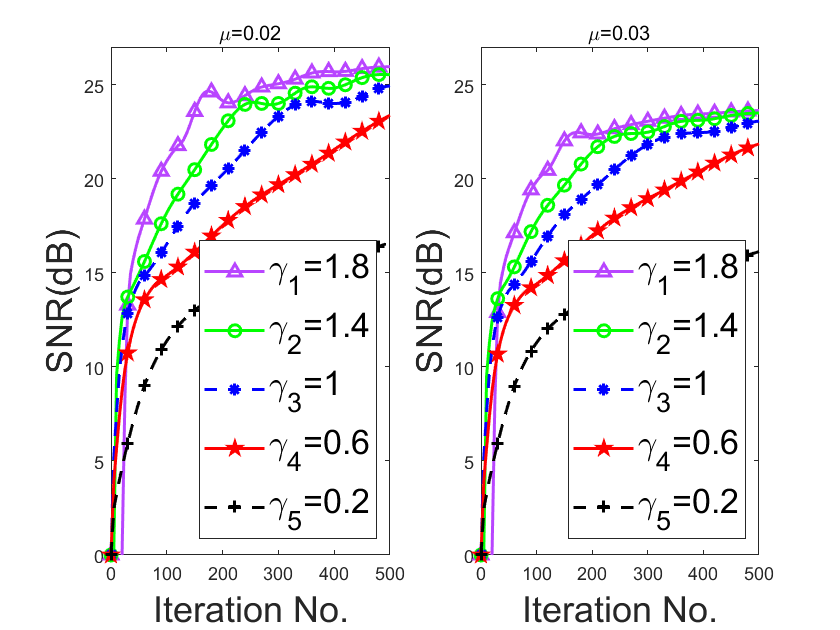

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 500;
opts1.snr = 50;
gamma = [1.8,1.4,1,0.6,0.2];
[~,N] = size(gamma);
reimed1 = zeros(N,rows,cols);reimed2 = zeros(N,rows,cols);
for i = 1:N
    opts1.gamma = gamma(i);
    [reimed1(i,:,:),outs1(i)] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);
    [reimed2(i,:,:),outs2(i)] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);    
end

%% 绘图
Xaxis = (0:5:500);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\gamma_1=1.8}','{\gamma_2=1.4}','{\gamma_3=1}','{\gamma_4=0.6}','{\gamma_5=0.2}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.02','FontSize',19);

subplot(122);
plot(Xaxis,outs2(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\gamma_1=1.8}','{\gamma_2=1.4}','{\gamma_3=1}','{\gamma_4=0.6}','{\gamma_5=0.2}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.03','FontSize',19);

% set(gcf,'unit','centimeters','position',[1,2,30,12])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg2_3.gamma.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg2_3.gamma.fig')

## Delta

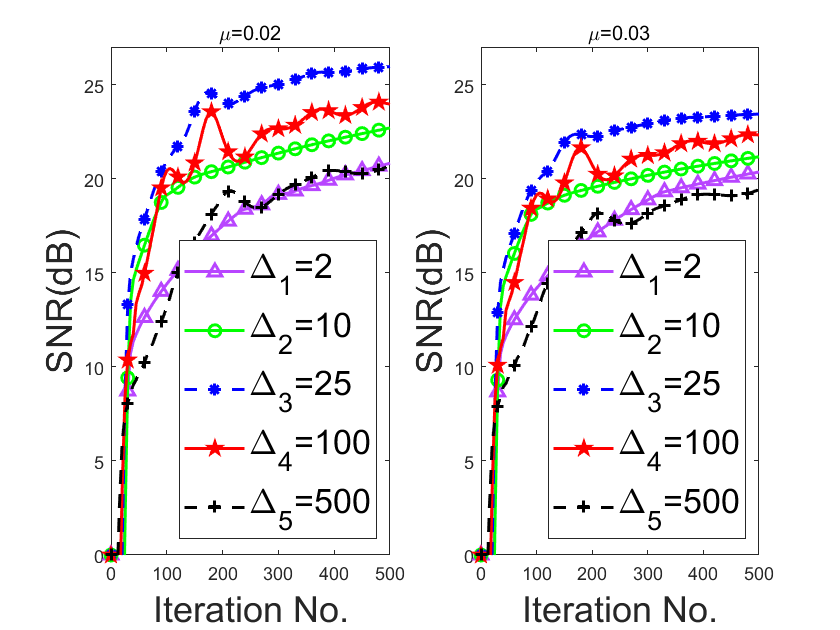

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 500;
opts1.snr = 50;
Delta = [2,10,25,100,500];
[~,N] = size(Delta);
reimed1 = zeros(N,rows,cols);reimed2 = zeros(N,rows,cols);
for i = 1:N
    opts1.Delta = Delta(i);
    [reimed1(i,:,:),outs1(i)] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);
    [reimed2(i,:,:),outs2(i)] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);    
end

%% 绘图
Xaxis = (0:5:500);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\Delta_1=2}','{\Delta_2=10}','{\Delta_3=25}','{\Delta_4=100}','{\Delta_5=500}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.02','FontSize',19);

subplot(122);
plot(Xaxis,outs2(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\Delta_1=2}','{\Delta_2=10}','{\Delta_3=25}','{\Delta_4=100}','{\Delta_5=500}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.03','FontSize',19);

% set(gcf,'unit','centimeters','position',[1,2,30,12])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg2_4.Delta.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg2_4.Delta.fig')

## eta

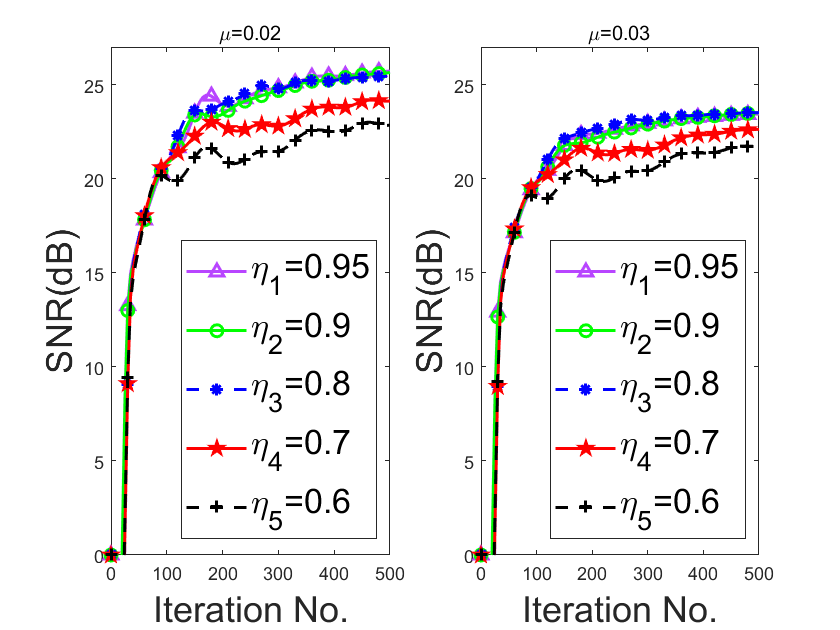

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 500;
opts1.snr = 50;
eta = [0.95,0.9,0.8,0.7,0.6];
[~,N] = size(eta);
reimed1 = zeros(N,rows,cols);reimed2 = zeros(N,rows,cols);
for i = 1:N
    opts1.eta = eta(i);
    [reimed1(i,:,:),outs1(i)] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);
    [reimed2(i,:,:),outs2(i)] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);    
end

%% 绘图
Xaxis = (0:5:500);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\eta_1=0.95}','{\eta_2=0.9}','{\eta_3=0.8}','{\eta_4=0.7}','{\eta_5=0.6}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.02','FontSize',19);

subplot(122);
plot(Xaxis,outs2(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\eta_1=0.95}','{\eta_2=0.9}','{\eta_3=0.8}','{\eta_4=0.7}','{\eta_5=0.6}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.03','FontSize',19);

% set(gcf,'unit','centimeters','position',[1,2,30,12])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg2_5.eta.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg2_5.eta.fig')

## nu

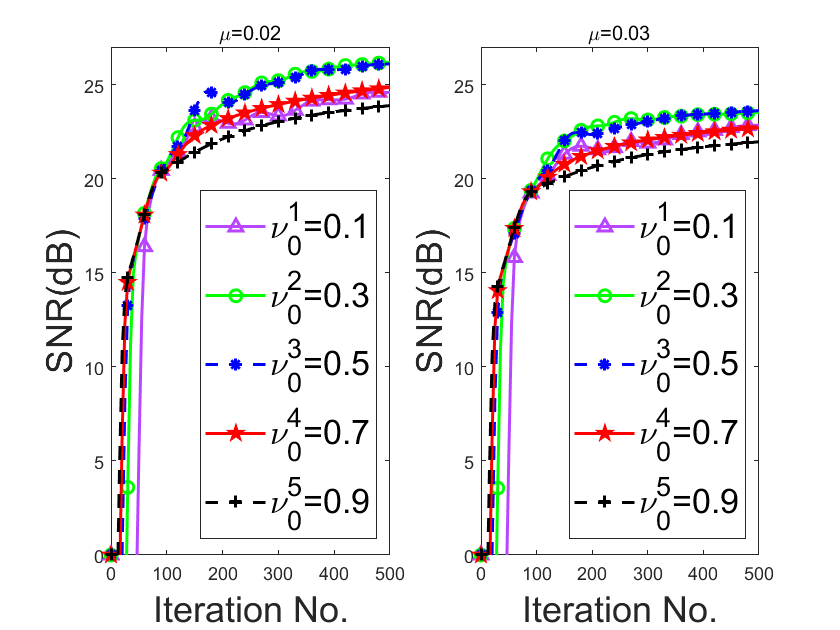

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 500;
opts1.snr = 50;
nu = [0.1,0.3,0.5,0.7,0.9];
[~,N] = size(nu);
reimed1 = zeros(N,rows,cols);reimed2 = zeros(N,rows,cols);
for i = 1:N
    opts1.a = nu(i);
    [reimed1(i,:,:),outs1(i)] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);
    [reimed2(i,:,:),outs2(i)] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);    
end

%% 绘图
Xaxis = (0:5:500);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\nu_0^1=0.1}','{\nu_0^2=0.3}','{\nu_0^3=0.5}','{\nu_0^4=0.7}','{\nu_0^5=0.9}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.02','FontSize',19);

subplot(122);
plot(Xaxis,outs2(1).snr(Xaxis+1),'Color',[0.72,0.27,1.00],'LineWidth',1.5,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(2).snr(Xaxis+1),'g-','LineWidth',1.5,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(3).snr(Xaxis+1),'b--','LineWidth',1.5,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(4).snr(Xaxis+1),'r-','LineWidth',1.5,'Marker','p','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2(5).snr(Xaxis+1),'k--','LineWidth',1.5,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;axis([Xaxis(1),Xaxis(end),0,27]);
legend('{\nu_0^1=0.1}','{\nu_0^2=0.3}','{\nu_0^3=0.5}','{\nu_0^4=0.7}','{\nu_0^5=0.9}','FontSize',17,'Location','SouthEast');
xlabel('Iteration No.','FontSize',18);ylabel('SNR(dB)','FontSize',18);title('\mu=0.03','FontSize',19);

% set(gcf,'unit','centimeters','position',[1,2,30,12])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg2_6.nu.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg2_6.nu.fig')